# Homework 13

## [✔] ADSI Problem 7.1

A tremendous amount of functionality is found in MATLABs toolboxes and Hilbert transforms are no exception. Type doc hilbert in MATLAB and read the documentation.  

doc hilbert

## [✔] ADSI Problem 7.2: Hilbert transform of a cosine signal

*A continuous time signal is given by *$x\left(t\right)=4+3\mathrm{cos}\left(\omega t\right)$*. What is the Hilbert transform of this signal?  *

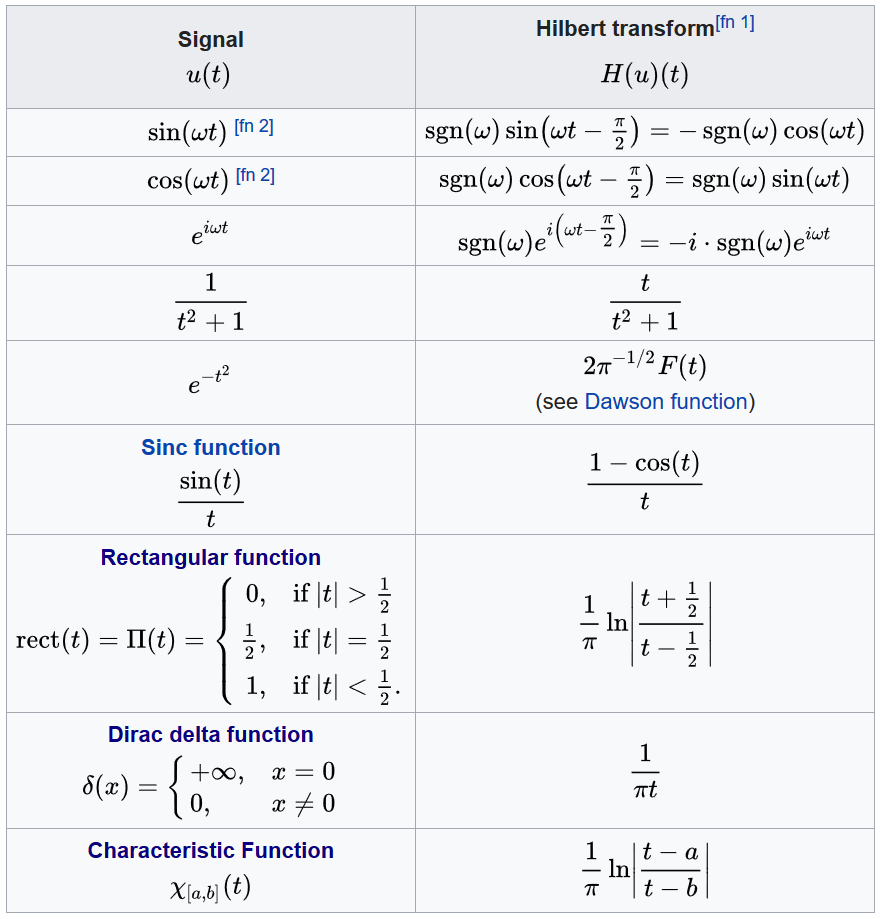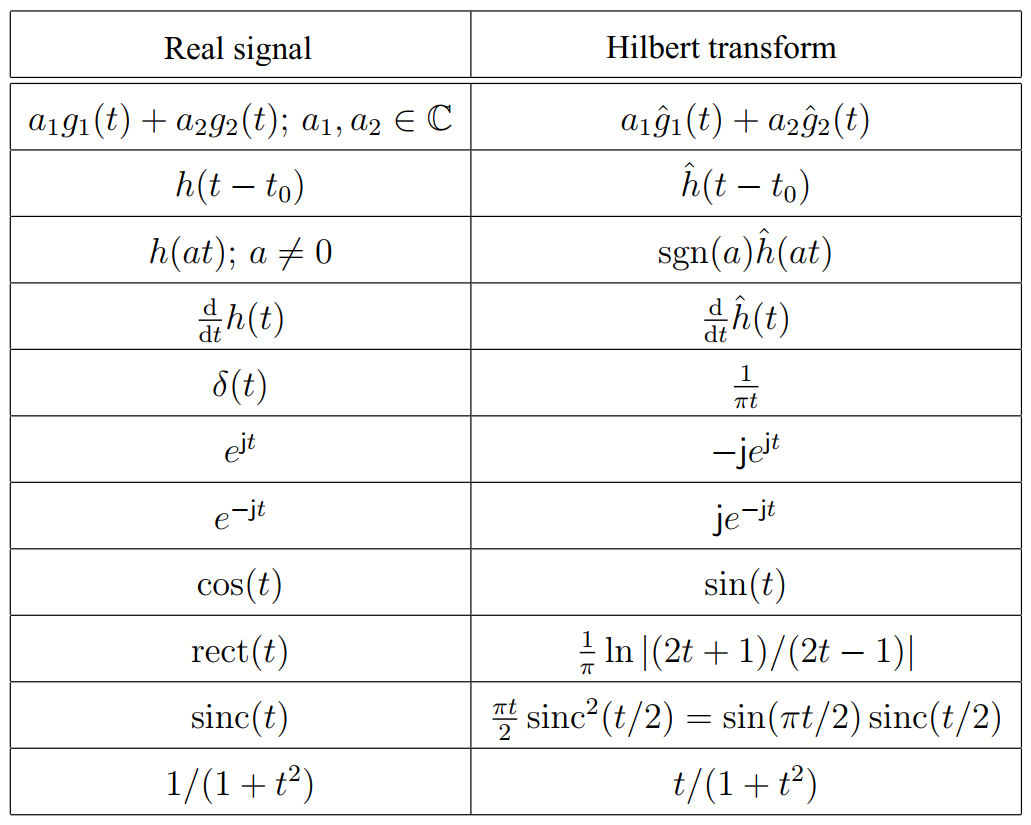


$$H\left\lbrack 4+3\;\mathrm{cos}\left(\omega t\right)\right\rbrack =H\left\lbrack 4\right\rbrack +3H\left\lbrack \mathrm{cos}\left(\omega t\right)\right\rbrack$$



$$H\left\lbrack 4+3\;\cos \left(\omega t\right)\right\rbrack =0+3\mathrm{sgn}\left(\omega \right)\mathrm{sin}\left(\omega t\right)$$
 

## [✔] ADSI Problem 7.3: One-sided spectrum of analytical signals

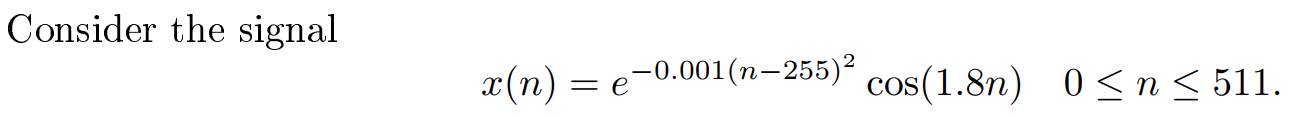

*Calculate the analytical signal in MATLAB and check that the spectrum is one-sided as expected.  *

Recall that we start with a real-valued signal $x_r \left(t\right)$ and we want we need to represent the signal as a complex sinusoid:

        
$$x_c \left(t\right)=x_r \left(t\right)+j\;x_i \left(t\right)$$


$x_c \left(t\right)$ is known as an ***analytic signal*** because it has no negative-frequency spectral components.

To show that the spectrum is one-sided, we have to show that the frequency response $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. 

We can do this by estimating the power spectrum density (PSD) of the analytical signal using the periodogram.

In the MATLAB plot, the normalised **positive frequency range** is [0, 1] whereas the **negative frequency range** is between 1 and 2. Notice there is no power spikes in the negative frequency range, only noise.

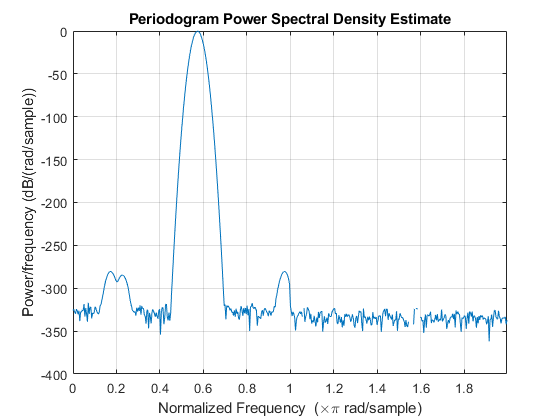

n = (0:511)';
x = exp(-0.001.*(n-225).^2).*cos(1.8*n);

% Compute the analytic signal of the real signal x(n)
y = hilbert(x);

% Compute and plot the PSD estimate
periodogram(y)

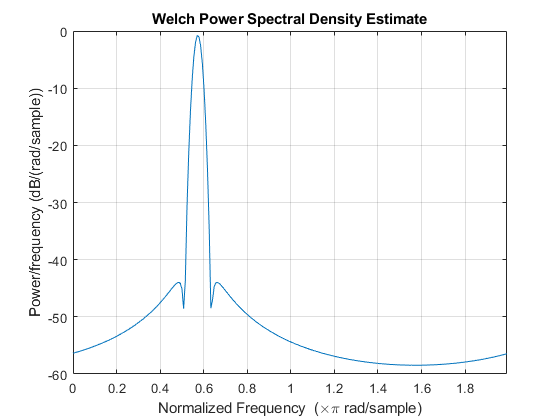

% PSD estimate using the Welch method
pwelch(y)

## [»] ADSI Problem 7.4: Swept sine wave

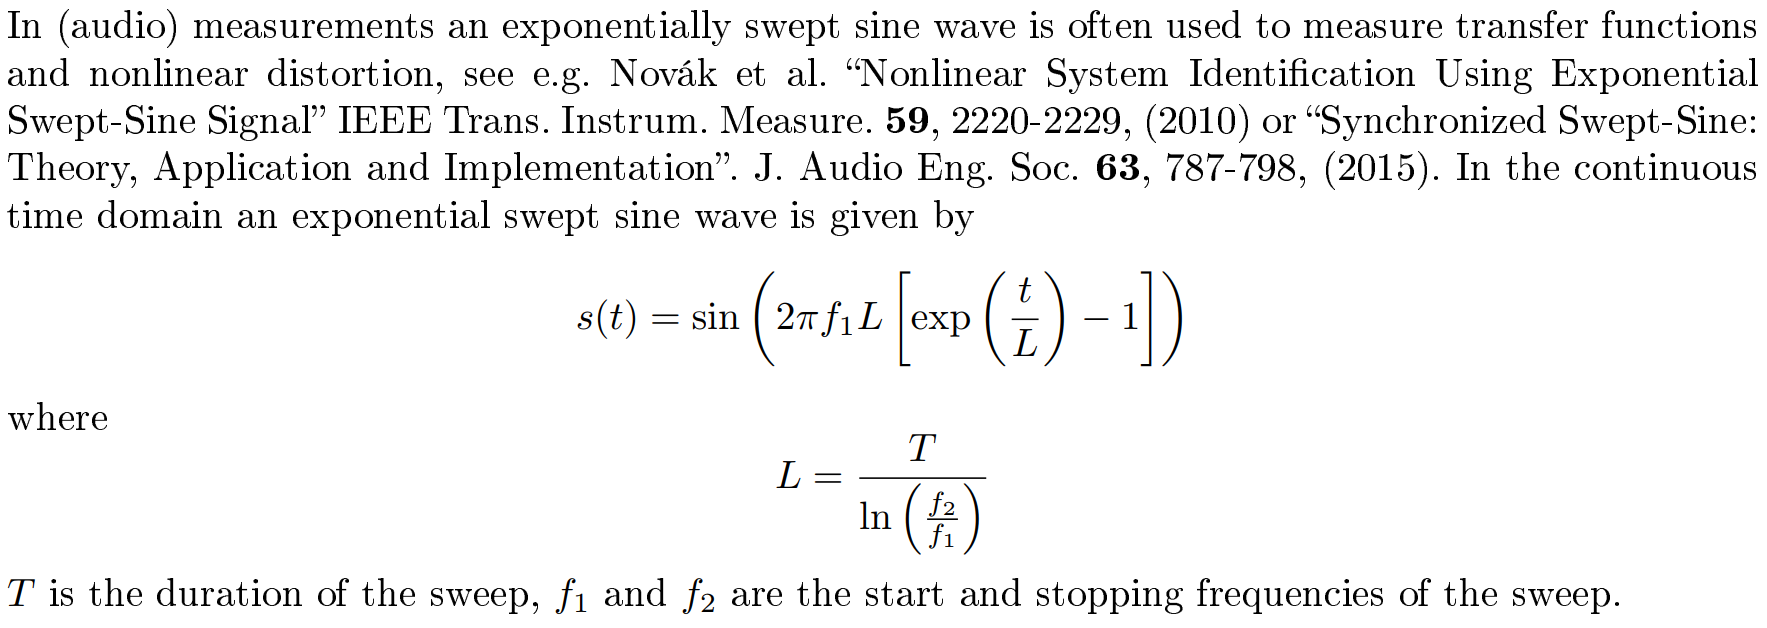

### 1. Design swept sine signal

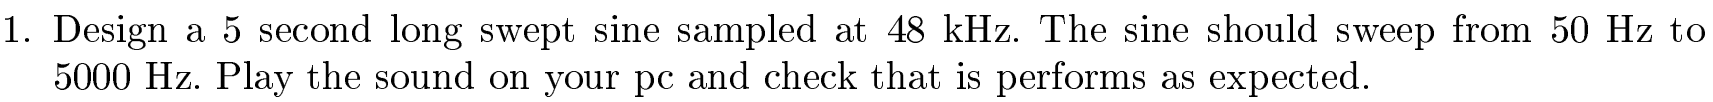

### 2. Compute instantaneous frequency

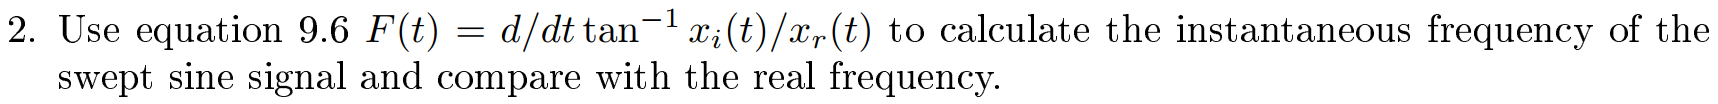

## [»] ADSI Problem 7.5: Envelope Detection

*The textbook states that the Hilbert transform can be used to find the envelope of a signal. The validity of this statement is investigated in this problem. *

*Consider an exponentially decaying oscillating signal given by*

        
$$x\left(n\right)=4e^{-0\ldotp 01n} \mathrm{cos}\left(\pi n\right)$$


### 1. Plot the signal and envelope on the same graph

*Plot this signal and use equation 9.4 to plot the envelope on the same graph. Compare the result with the expected outcome.*

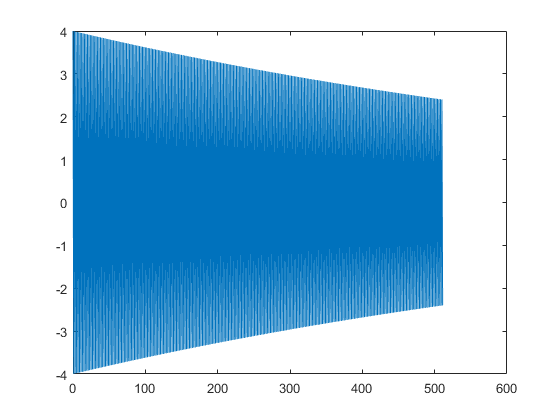

n = (0:511)';
x = 4*exp(-0.001.*n).*cos(pi*n);
plot(n, x)

### 2. Describe how noise affects Hilbert transform's ability to recover the envelope

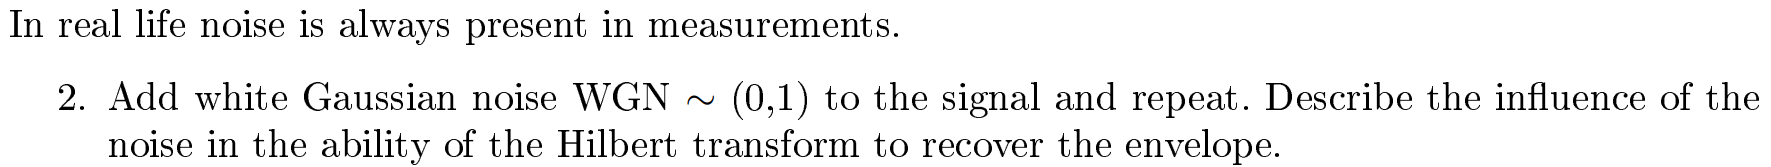

### 3. Try with other two signals

## [»] ADSI Problem 7.8: Amplitude modulated signal

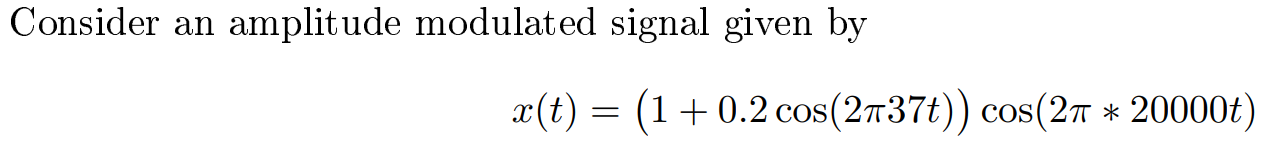

### 1. Plot 1 second of the signal and confirm that it is an amplitude modulated signal with a carrier frequency of 20 kHz.  

### 2. Use the procedure from Figure 9.8 in the note to frequency shift the signal to 15 kHz. Plot the spectrum of the signal at each step in the procedure.  